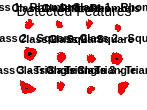

% Run script to that loads:
% 1. descripRho;
% 2. descripSqu; 
% 3. descripTri;
run('lab5_buildDescriptors.m');   

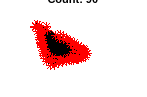

% Load test image
testImg = imread(['./Data/datasetImages/tri_test(1).jpg']);  

% Detect and extract SURF features 
testPoints  = detectSURFFeatures(testImg);
[testDescriptors, testPoints] = extractFeatures(testImg, testPoints);

% Visualise detected interest points on the test image
figure('Name', 'Test Image – Detected Interest Points');
imshow(testImg); hold on;
plot(testPoints.Location(:,1), testPoints.Location(:,2), 'r*');
title(sprintf('Test Image Interest Points\nCount: %d', testPoints.Count));
hold off;


%% ── 2.3    Match test descriptors against each class ──────────────────────
% Match against each class descriptor using matchFeatures
matchesRho = matchFeatures(testDescriptors, descripRho.Features);
matchesSqu = matchFeatures(testDescriptors, descripSqu.Features);
matchesTri = matchFeatures(testDescriptors, descripTri.Features);

numMatchRho = size(matchesRho, 1);
numMatchSqu = size(matchesSqu, 1);
numMatchTri = size(matchesTri, 1);

%% ── 2.4  Classify based on highest number of matches ────────────────────
numMatches = [numMatchRho, numMatchSqu, numMatchTri];
classNames = {'Rhombus', 'Square', 'Triangle'};

[~, idx]       = max(numMatches);
predictedClass = classNames{idx};

fprintf('\n========== Classification Result ==========\n');


========== Classification Result ==========


fprintf('Matches with Rhombus  : %d\n', numMatchRho);

Matches with Rhombus  : 17


fprintf('Matches with Square   : %d\n', numMatchSqu);

Matches with Square   : 16


fprintf('Matches with Triangle : %d\n', numMatchTri);

Matches with Triangle : 90


fprintf('-------------------------------------------\n');

-------------------------------------------


fprintf('Predicted Class       : %s\n', predictedClass);

Predicted Class       : Triangle


fprintf('===========================================\n');

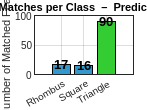


%% ── 2.5  Bar chart of match counts ──────────────────────────────────────
figure('Name', 'Classification Match Counts');
b = bar(numMatches, 'FaceColor', 'flat');
b.CData(1,:) = [0.2 0.6 0.8];
b.CData(2,:) = [0.2 0.6 0.8];
b.CData(3,:) = [0.2 0.6 0.8];
b.CData(idx,:) = [0.2 0.8 0.2];   % highlight winning class in green

set(gca, 'XTickLabel', classNames);
ylabel('Number of Matched Features');
title(sprintf('Feature Matches per Class  –  Predicted: %s', predictedClass));
grid on;

for i = 1:3
    text(i, numMatches(i) + max(numMatches)*0.01, num2str(numMatches(i)), ...
        'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end


%% ── 2.6  Visualise matches against the predicted class ──────────────────
% Reload the first build image of the predicted class for visualisation
switch idx
    case 1,  buildImg = imread('./datasetImages/rho_build(3).jpg');
    case 2,  buildImg = imread('./datasetImages/squ_build(3).jpg');
    case 3,  buildImg = imread('./datasetImages/tri_build(3).jpg');
end

Error using imread>get_full_filename
File "./datasetImages/tri_build(3).jpg" does not exist.

Error in imread (line 372)
        fullname = get_full_filename(filename);


if size(buildImg, 3) == 3
    buildGray = rgb2gray(buildImg);
else
    buildGray = buildImg;
end

buildPoints = detectSURFFeatures(buildGray);
[buildDescriptors, buildPoints] = extractFeatures(buildGray, buildPoints);

indexPairs = matchFeatures(testDescriptors, buildDescriptors);

matchedTest  = testPoints(indexPairs(:,1));
matchedBuild = buildPoints(indexPairs(:,2));

figure('Name', 'Matched Features – Test vs Predicted Class');
showMatchedFeatures(testGray, buildGray, matchedTest, matchedBuild, 'montage');
title(sprintf('Matched Features: Test Image  vs  %s (predicted)', predictedClass));